% This code compares the calibration data between manual calibration and
% the data sheet calibraiton numbers. Manual calibration data was collected
% with the calibrationLoop method. All fitted models were created using
% cftool and using the power relationship since it had the best fit among
% all the available fit types.
dataSheetCalibration = [15 2.75; 20 2.55; 30 2; 40 1.55; 50 1.25; 60 1.05; 70 0.9; 80 0.8;
                         90 0.7; 100 0.6; 110 0.55; 120 0.52; 130 0.5; 140 0.48; 150 0.49];
load("fitteddecaymodel.mat"); %created with fittool gui and power relationship
hold on
plot(distanceData(:,1), distanceData(:,2), '*')
%plot(errorMatchData(:,1), errorMatchData(:,2), 'o')
plot(dataSheetCalibration(:,1),dataSheetCalibration(:,2),'^')
plot(powermanualmodel, '.-') %created with the fittool gui and power relationship

plot(fittedmodel, '--')

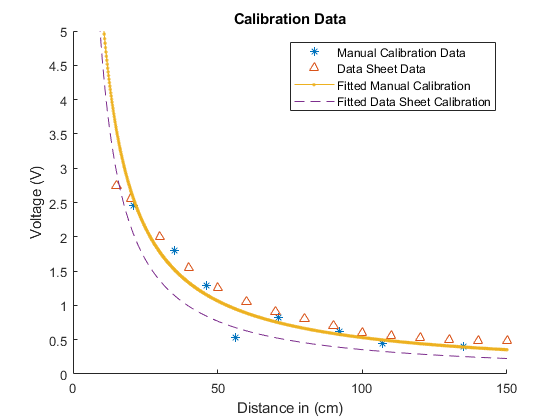

ylim([0,5])
title("Calibration Data")
ylabel("Voltage (V)")
xlabel("Distance in (cm)")
legend("Manual Calibration Data","Data Sheet Data","Fitted Manual Calibration","Fitted Data Sheet Calibration")
hold off

voltages = linspace(0.5,5,50);
dy = zeros(50,1); % absolute error
dyp = zeros(50,1); % percent error
for index = 1 : 50
    dy(index) = abs(powermanualmodel(voltages(index)) - fittedmodel(voltages(index)));
    dyp(index) = dy(index)/fittedmodel(voltages(index))*100;
end
disp("Average absolute error (cm): ")

Average absolute error (cm): 


disp(mean(dy))

    2.6416



disp("Average percent error: " )

Average percent error: 


disp(mean(dyp))

    5.3881

